## Loading memories from images

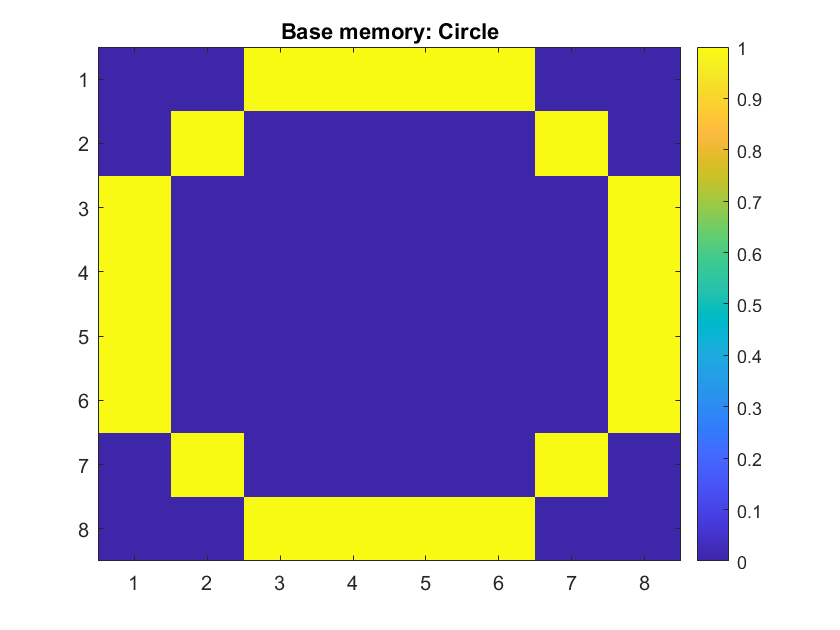

clear all;

% Import images as an matrix with values between 0 and 1
img_cir = rgb2gray(imread('Images/circle.png')) / 255;
img_squ = rgb2gray(imread('Images/square.png')) / 255;
img_tri = rgb2gray(imread('Images/triangle.png')) / 255;
img_cre = rgb2gray(imread('Images/crecent.png')) / 255;

% Print memories
image(img_cir,'CDataMapping','scaled')
title("Base memory: Circle")
colorbar

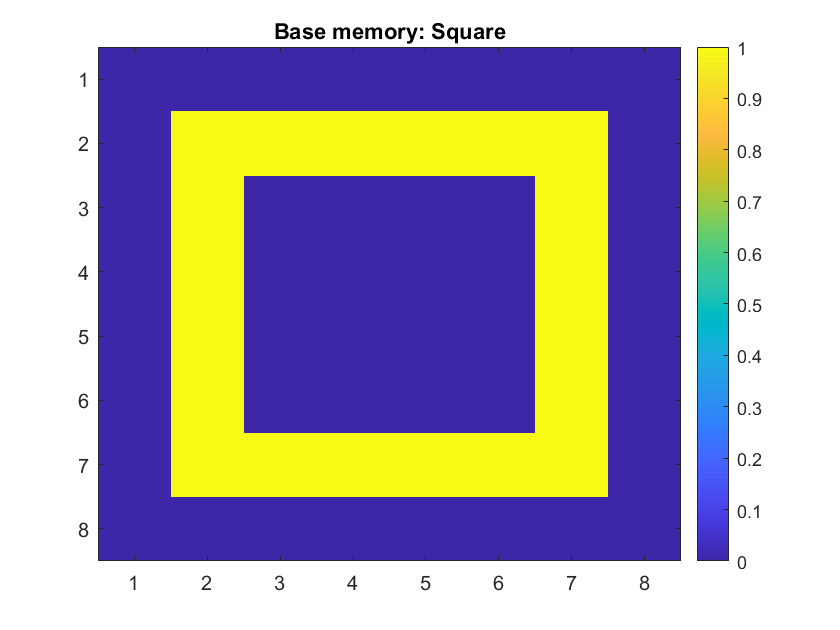

image(img_squ,'CDataMapping','scaled')
title("Base memory: Square")
colorbar

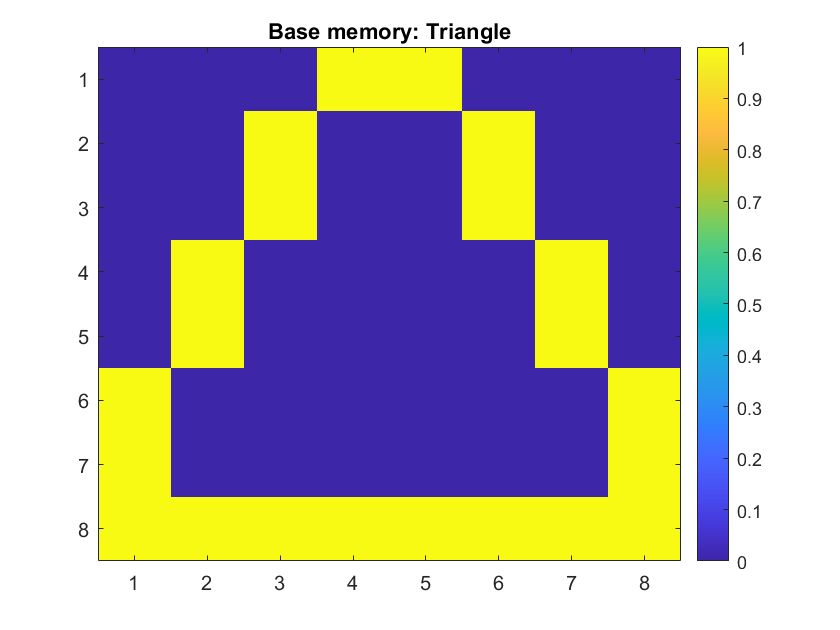

image(img_tri,'CDataMapping','scaled')
title("Base memory: Triangle")
colorbar

%image(img_cre,'CDataMapping','scaled')
%title("Base memory: Crecent")
%colorbar

% Rescale the matrices to vectors
Memories.cir = reshape(img_cir,1,[]);
Memories.squ = reshape(img_squ,1,[]);
Memories.tri = reshape(img_tri,1,[]);
%Memories.cre = reshape(img_cre,1,[]);

## Generating the weigth matrix from the memories

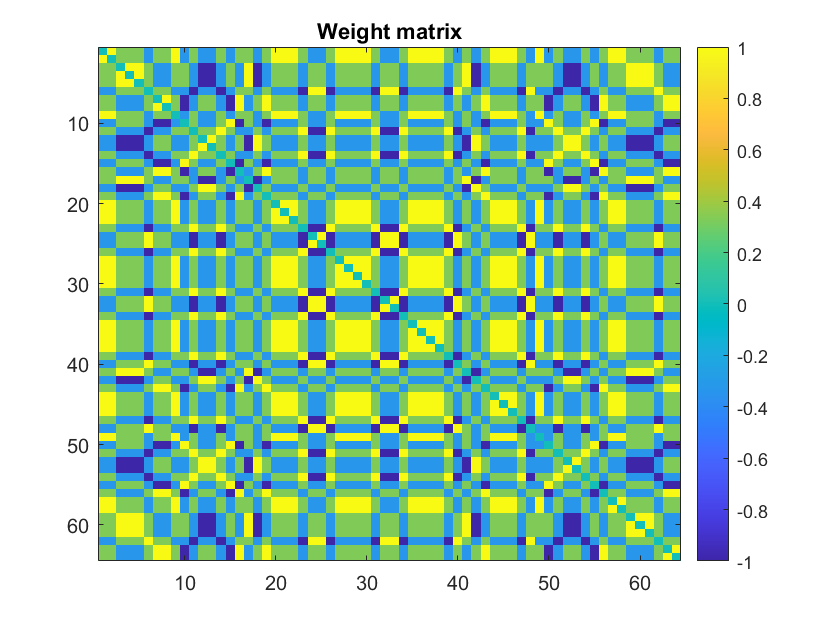

% Define weight matrix
W = zeros(64,64);

% For each memory we want to store in the network
mem_names = fieldnames(Memories);
for idx = 1:numel(mem_names)
    % Compute its inpact on the weigth values:
    mem_vec = double(Memories.(mem_names{idx}));
    W = W + 4 * (mem_vec' - 0.5) * (mem_vec - 0.5);
end

% Normalise W by the amount of memories
W = W / numel(mem_names);

% Remove self connections (diagonal)
W = W - eye(64);

image(W,'CDataMapping','scaled')
title("Weight matrix")
colorbar

## Defining the user input

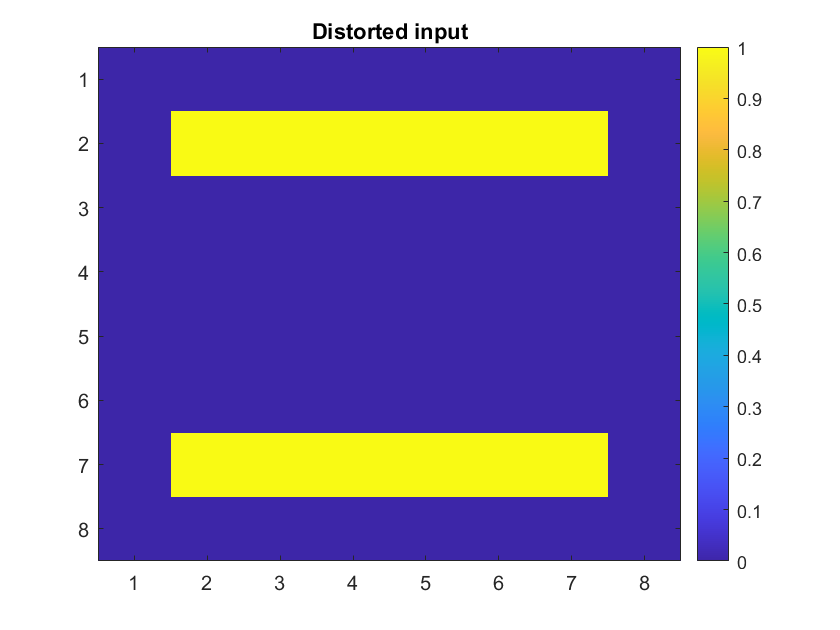

test_img = [
    0 0 0 0 0 0 0 0
    0 1 1 1 1 1 1 0
    0 0 0 0 0 0 0 0
    0 0 0 0 0 0 0 0
    0 0 0 0 0 0 0 0
    0 0 0 0 0 0 0 0
    0 1 1 1 1 1 1 0
    0 0 0 0 0 0 0 0];
image(test_img,'CDataMapping','scaled')
title("Distorted input")
colorbar


% Map the input values to a vector with {-1,1}
input_vec = 2 * (reshape(test_img,[],1) - 0.5);

## Define Simulation parameters

num_Neuron = 64;
sim_time=1000;           % simulation time, ms^-1

step=0.5;
I_scaling_factor = 30;   % Should test different values (!)

a = 0.02 * ones(64,1);   % Time scale of recovery u(t),
b = 0.2  * ones(64,1);   % Sensitivity of u(t) to fluctuations in v(t)
c = -65  * ones(64,1);   % After spike reset value of v(t)
d = 8    * ones(64,1);   % After spike reset of u(t)

## Initialising simulation variables

v=-65*ones(num_Neuron,1);    % Initial values of v
u=b.*v;                 % Initial values of u
firings=[];             % spike timings
stateV=zeros(sim_time,num_Neuron);
stateU=zeros(sim_time,num_Neuron);
X = rand(num_Neuron, sim_time); % sequence of uniformly distributed random numbers
dv = @(v,u,I,dt)    dt * (0.04*v.^2 + 5*v + 140 - u + I);
du = @(v,u,a,b,dt)  dt * a.*(b.*v - u);

## Run simulation

for t = 1:sim_time                        % simulation of 100 ms with a microsecond resolution
  I = poisson_spikes(input_vec, X, I_scaling_factor, t);
  fired = find(v>=30);                  % indices of spikes
  firings = [firings; t+0*fired,fired]; % add fired neurons to the firings matrix
  v(fired) = c(fired);                  % reset voltage of fired neurons
  u(fired) = u(fired) + d(fired);       % reset recovery variable of fired neurons
  I = I + sum(W(:,fired),2);            % Add input from fired neurons
  v = v + step*dv(v,u,I,1);
  u = u + du(v,u,a,b,1);
  stateV(t,:) = v(:,:);
  stateU(t,:) = u(:,:);
end

## Plotting results

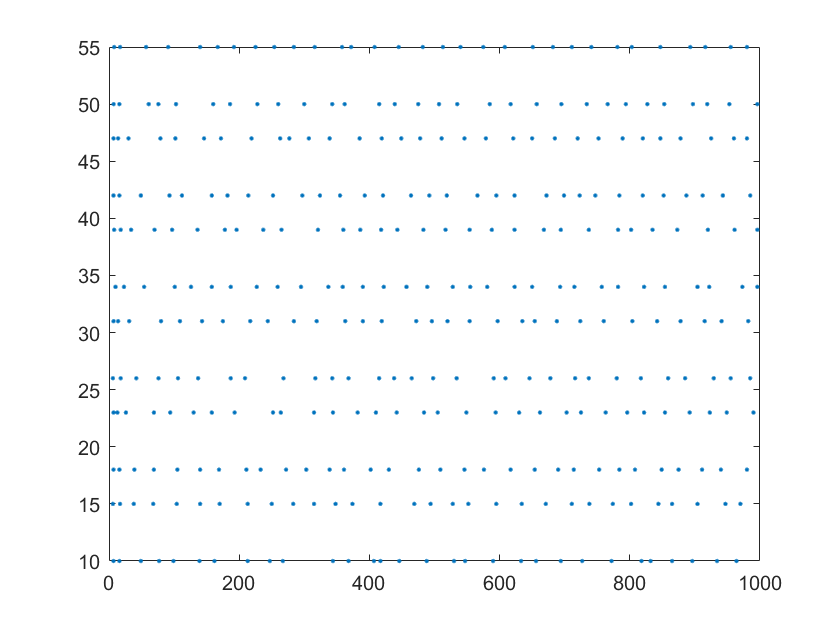

% Plot fired neurons over time
plot(firings(:,1),firings(:,2),'.');

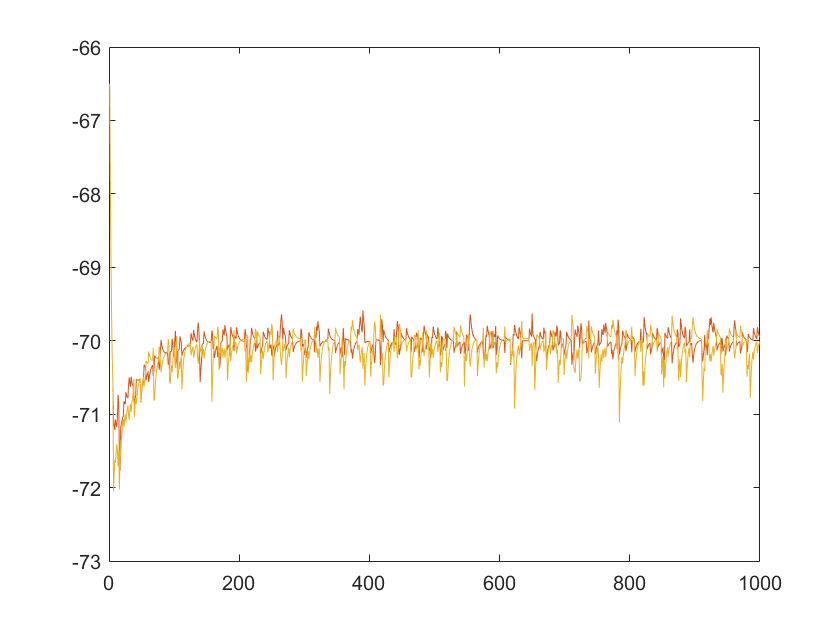


% Plotthe state over time of neuron 1
plot(1:sim_time, stateV(:,1:3))

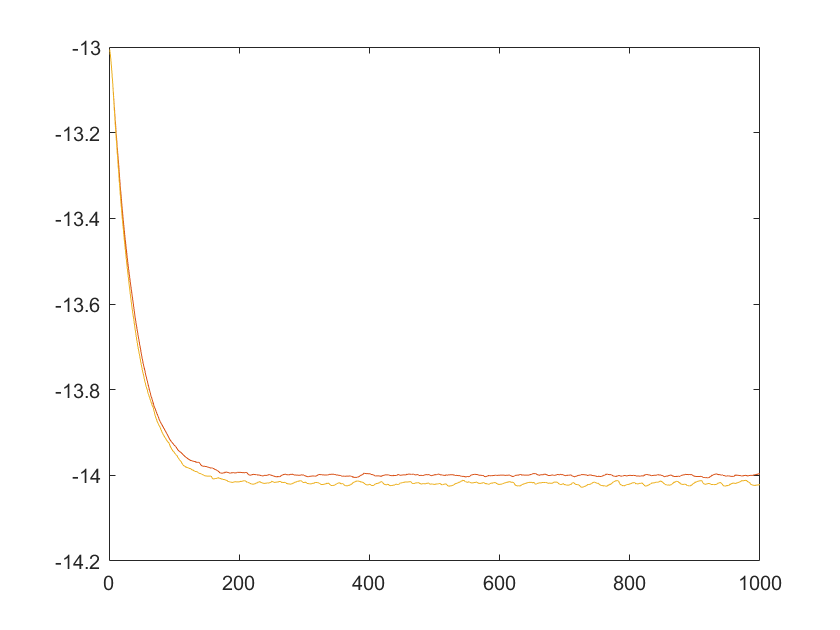

plot(1:sim_time, stateU(:,1:3))

## Functions

function I = poisson_spikes(input_vec, X, I_scaling_factor, t)    
  I=X(:,t);                  % initialize I with the random uniformly distributed values for spikes;
  diff = input_vec - X(:,t); % find the indices of neurons
  idx = find(diff<0);        % where pixel value < random number
  I(idx) = 0;                % and produce no spike in that case;
  I = I_scaling_factor*I;    % scale the resulting spikes;
end